# Time-Varying Fan Signal

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/monitoredfan.mat 
n = length(monitoredfan)

n = 1200000

## Task 1

In this activity, you'll compute the spectrogram for the vibration signal of computer fan. This generated signal simulates the vibration signal for about 8 minutes. Using the critical frequencies from the previous module, you'll see that at some point, the computer fan broke.

As you saw on the previous page, if you use a method like periodogram to find the spectrum of a time-varying signal, you'll lose all the time information. Before you make a spectrogram, first use Welch's method to see what happens.

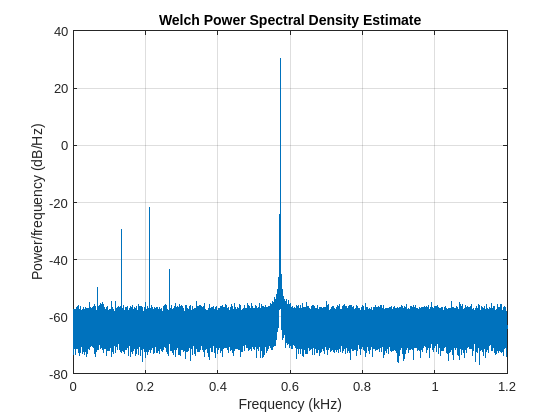

pwelch(monitoredfan,[],[],[],fs)

## Task 2

In the spectrum, you can't tell what time any of these frequencies occurred. The spectrogram can help you find what time the fan stopped working properly.

The inputs to `spectrogram` are the same as `pwelch`.

`spectrogram``(``s``,``window``,``numoverlap``,``nfft``,``fs``)`

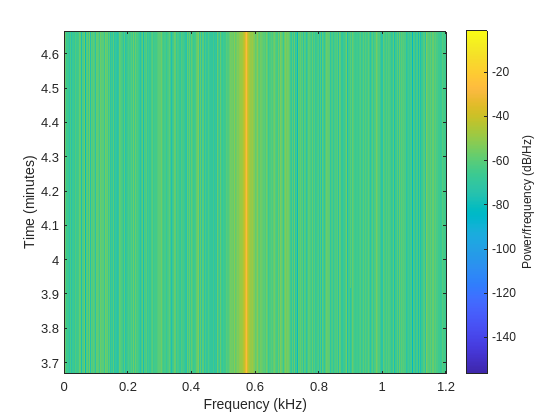

spectrogram(monitoredfan,ones(n,1),0,2^12,fs)

## Task 3

Even though the fan signal varies over time, this spectrogram shows that the frequencies do not change.

The window is the same length as the signal, so it isn't divided before the spectrum is calculated. To see how the signal changes over time, use a smaller window.

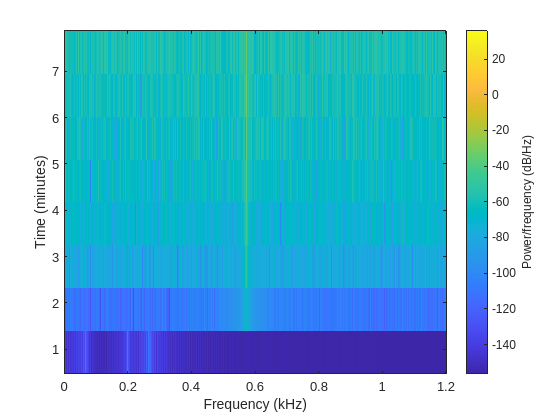

spectrogram(monitoredfan,[],[],[],fs)

## Task 4

Another value that you might want to change is the frequency axis. You can swap the axes so that frequency is on the y-axis and time is on the x-axis.

`spectrogram``(``s``,``window``,``numoverlap``,``...`

`nfft``,``fs``,``"yaxis"``)`

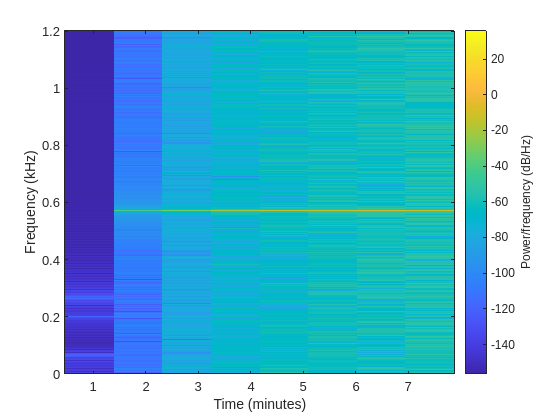

spectrogram(monitoredfan,[],[],[],fs,"yaxis")